# Behavioral data analysis

Multilevel GLM to examine the effects of temperature and regulation (and their interactions) on pain ratings (to run this, you need to install CanlabCore https://github.com/canlab/CanlabCore)

clear all;
close all;
load('../data/CRB_dataset_SCR_lpf5Hz_DS25Hz_011516.mat');

for i = 1:numel(D.Event_Level.data)
    y_int{i} = D.Event_Level.data{i}(:,12);         % intensity ratings: 0 to 100
    y_unp{i} = -2*(D.Event_Level.data{i}(:,13)-50); % unpleasant ratings: -100 to 100
    xx{i} = [D.Event_Level.data{i}(:,11) D.Event_Level.data{i}(:,16) ...
        scale(D.Event_Level.data{i}(:,11),1).*scale(D.Event_Level.data{i}(:,16),1)];
                                                    % xx: independent variable 
                                                    % temperature, regulation, and 
                                                    % interaction between temperature and regulation
    reg{i} = D.Event_Level.data{i}(:,16);
    temp{i} = D.Event_Level.data{i}(:,11);
end

% multilevel GLM analysis for intensity ratings with bootstrap tests (10000 iterations)
stats{1} = glmfit_multilevel(y_int, xx, [], 'names', {'intcp', 'temp', 'reg', 'intera'}, ...
    'weighted', 'verbose', 'boot', 'nresample', 10000);

Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  41, Predictors:   1
Outcome names: intcp	temp	reg	intera	
Weighting option: weighted
Inference option: bootstrap

Other Options:
	Plots: No
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	R & B - type Empirical Bayes reweighting.
 Min p-value is 0.000000. Needed: 10000 samples
 Bootstrapping 10000 samples... Bootstrap done in 0.10 s, bias correct in 0.00 s 
Total time: 2.17 s

________________________________________
Average p-value tolerance (average max alpha): 0.0060

Bootstrapped statistics. Bootstrap inference
	Outcome variables:
	intcp	temp	reg	intera	
Adj. mean	-211.58	4.94	1.99	0.49	

2nd-level B01
	intcp	temp	reg	intera	
Coeff	-211.59	4.94	2.00	0.49	
STE	12.28	0.28	0.31	0.12	
t	-15.31	15.70	5.87	4.04	
Z	-3.48	3.60	3.72	3.71	
p	0.0003	0.0002	0.0001	0.0001	

________________________________________


% multilevel GLM analysis for unpleasantness ratings with bootstrap tests (10000 iterations)
stats{2} = glmfit_multilevel(y_unp, xx, [], 'names', {'intcp', 'temp', 'reg', 'intera'}, ...
    'weighted', 'verbose', 'boot', 'nresample', 10000); 

Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  41, Predictors:   1
Outcome names: intcp	temp	reg	intera	
Weighting option: weighted
Inference option: bootstrap

Other Options:
	Plots: No
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	R & B - type Empirical Bayes reweighting.
 Min p-value is 0.000000. Needed: 10000 samples
 Bootstrapping 10000 samples... Bootstrap done in 0.03 s, bias correct in 0.00 s 
Total time: 2.29 s

________________________________________
Average p-value tolerance (average max alpha): 0.0060

Bootstrapped statistics. Bootstrap inference
	Outcome variables:
	intcp	temp	reg	intera	
Adj. mean	-240.38	5.41	4.91	0.21	

2nd-level B01
	intcp	temp	reg	intera	
Coeff	-240.31	5.41	4.92	0.22	
STE	14.95	0.34	0.55	0.17	
t	-14.24	14.33	7.63	1.17	
Z	-3.63	3.43	4.15	0.96	
p	0.0001	0.0003	0.0000	0.1686	

________________________________________


## Plotting the effects of temperature and regulation on pain ratings (intensity and unpleasantness)

Plot for intensity ratings (Figure 2 in the manuscript)

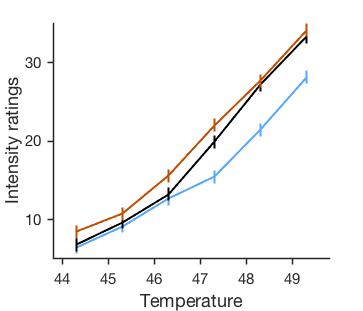

clear dat*; 

dosavefig = false; % save figure in matlab 2014 (was written in 2014 previously)
figdir = '../figures';

u_temp = unique(temp{1});
u_reg = unique(reg{1});

for subj = 1:numel(temp)
    for i = 1:numel(u_temp)
        for j = 1:numel(u_reg)
            dat_int{subj}(i,j) = nanmean(y_int{subj}(temp{subj}==u_temp(i) & reg{subj}==u_reg(j)));
            dat_unp{subj}(i,j) = nanmean(y_unp{subj}(temp{subj}==u_temp(i) & reg{subj}==u_reg(j)));
        end
    end
end

for subj = 1:numel(temp)
    reg_all{1}(:,subj) = dat_int{subj}(:,1);
    reg_all{2}(:,subj) = dat_int{subj}(:,2);
    reg_all{3}(:,subj) = dat_int{subj}(:,3);
end

x = 44.3:1:49.3;
y = [mean(reg_all{1},2) mean(reg_all{2},2) mean(reg_all{3},2)];
% se = [repmat(wsbar(reg_all{1}'), 6, 1) repmat(wsbar(reg_all{2}'), 6, 1) repmat(wsbar(reg_all{3}'), 6, 1)];
se = repmat(barplot_get_within_ste([reg_all{1}; reg_all{2}; reg_all{3}]'), 6, 3);

create_figure('plot');
if dosavefig
    set(gcf, 'Position', [1   512   268   194]);
else
    set(gcf, 'Position', [1   394   363   311]);
end

col = [0.3333    0.6588    1.0000
       0         0         0
       0.7608    0.3020    0];

for i = 1:3
    hold on;
    h = errorbar(x, y(:,i), se(:,i), 'color', col(i,:), 'linewidth', 2); %, 'markersize', 4, 'markerfacecolor', col(i,:));
    % sepplot(x, y(:,i), .75, 'color', col(i,:), 'linewidth', 2);
    % if dosavefig, errorbar_width(h, x, [0 0]); end
    h.CapSize = 0;
end

set(gca, 'xlim', [43.8 49.8], 'linewidth', 1.5, 'xtick', 44:49, 'tickdir',...
    'out', 'ticklength', [.02 .02], 'ytick', 0:10:50);
if dosavefig
    set(gca, 'fontsize', 20);
    
    %figdir = '/Users/clinpsywoo/Dropbox (CANLAB)/c_crb_analysis/analysis/figure';
    savename = fullfile(figdir, 'behavioral_int_full.pdf');
    pagesetup(gcf);
    saveas(gcf, savename);
    
    pagesetup(gcf);
    saveas(gcf, savename);
else
    set(gca, 'fontsize', 15);
    xlabel('Temperature', 'fontsize', 18);
    ylabel('Intensity ratings', 'fontsize', 18);
end

Plot for unpleasantness ratings (Figure 2 in the manuscript)

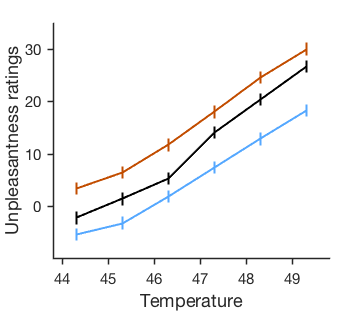

for subj = 1:numel(temp)
    reg_all{1}(:,subj) = dat_unp{subj}(:,1);
    reg_all{2}(:,subj) = dat_unp{subj}(:,2);
    reg_all{3}(:,subj) = dat_unp{subj}(:,3);
end

x = 44.3:1:49.3;
y = [mean(reg_all{1},2) mean(reg_all{2},2) mean(reg_all{3},2)];
se = repmat(barplot_get_within_ste([reg_all{1}; reg_all{2}; reg_all{3}]'), 6, 3);

create_figure('plot');
if dosavefig
    set(gcf, 'Position', [1   512   268   194]);
else
    set(gcf, 'Position', [1   394   363   311]);
end

col = [0.3333    0.6588    1.0000
       0         0         0
       0.7608    0.3020    0];

for i = 1:3
    hold on;
    h = errorbar(x, y(:,i), se(:,i), 'color', col(i,:), 'linewidth', 2); %, 'markersize', 4, 'markerfacecolor', col(i,:));
    % sepplot(x, y(:,i), .75, 'color', col(i,:), 'linewidth', 2);
    % if dosavefig, errorbar_width(h, x, [0 0]); end
    h.CapSize = 0;
end
set(gca, 'xlim', [43.8 49.8], 'ylim', [-10 35], 'linewidth', 1.5, 'xtick', 44:49, 'ytick', 0:10:30, 'tickdir', 'out', 'ticklength', [.02 .02]);
if dosavefig
    set(gca, 'fontsize', 20);
    
    %figdir = '/Users/clinpsywoo/Dropbox (CANLAB)/c_crb_analysis/analysis/figure';
    savename = fullfile(figdir, 'behavioral_unp_full.pdf');
    pagesetup(gcf);
    saveas(gcf, savename);
    
    pagesetup(gcf);
    saveas(gcf, savename);
else
    set(gca, 'fontsize', 15);
    xlabel('Temperature', 'fontsize', 18);
    ylabel('Unpleasantness ratings', 'fontsize', 18);
end

## Plotting glm results (pain intensity)

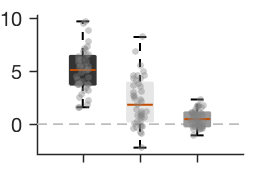


dosavefig = false;
edgecolor = 'k';
facecolor = [.2 .2 .2;
    .9 .9 .9;
    .6 .6 .6];

close all;
boxplot_wani_2016(stats{1}.first_level.beta(2:4,:)', 'color', facecolor, 'refline', 0, 'linewidth', 2, 'boxlinewidth', 3);
set(gcf, 'position',  [1   512   268   194]);
set(gca, 'fontsize', 20, 'linewidth', 1.5, 'ticklength', [.04 .04]);

h = scatter(reshape(repmat(1:3, 41, 1), 41*3,1)+scale(rand(41*3,1))/15, ...
    reshape(stats{1}.first_level.beta(2:4,:)', 41*3,1), 50, [.5 .5 .5], 'filled', 'MarkerFaceAlpha', .4);

if dosavefig
    savename = fullfile(figdir, 'int_glm_box.pdf');
    
    pagesetup(gcf);
    saveas(gcf, savename);
    
    pagesetup(gcf);
    saveas(gcf, savename);
else
    set(gca, 'fontsize', 15);
    xticklabels({'temp', 'reg', 'int'});
    ylabel('Effect magnitude', 'fontsize', 18);
    ylabel('Regressors', 'fontsize', 18);
end

## Plotting glm results (pain unpleasantness)

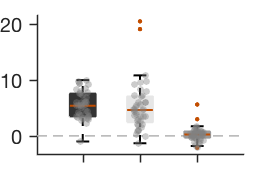


close all;
boxplot_wani_2016(stats{2}.first_level.beta(2:4,:)', 'color', facecolor, 'refline', 0, 'linewidth', 2, 'boxlinewidth', 3);
set(gcf, 'position',  [1   512   268   194]);
set(gca, 'fontsize', 20, 'linewidth', 1.5, 'ticklength', [.04 .04]); %, 'ylim', [-2.7997   12.2488]);

% Outliers are marked already
outlier_index = [59    64    92   100];
random_x = scale(rand(41*3,1))/15;

x = reshape(repmat(1:3, 41, 1), 41*3,1)+random_x;
x(outlier_index) = [];

y = reshape(stats{2}.first_level.beta(2:4,:)', 41*3,1);
y(outlier_index) = [];

h = scatter(x, y, 50, [.5 .5 .5], 'filled', 'MarkerFaceAlpha', .4);

if dosavefig
    savename = fullfile(figdir, 'unp_glm_box.pdf');
    
    pagesetup(gcf);
    saveas(gcf, savename);
    
    pagesetup(gcf);
    saveas(gcf, savename);
else
    set(gca, 'fontsize', 15);
    xticklabels({'temp', 'reg', 'int'});
    ylabel('Effect magnitude', 'fontsize', 18);
    ylabel('Regressors', 'fontsize', 18);
end